# Examen Análisis Numérico y Programación

1. Diseñar un programa function que calcula la adjunta de una matriz A de orden nxn. Compilar el programa con la matriz:


$$A=\left\lbrack \begin{array}{ccc}
2 & 4 & 3\\
0 & 1 & -1\\
3 & 5 & 7
\end{array}\right\rbrack$$


% function Adj=Adjunta_Examen(A)
% %Este programa permite calcular la matriz adjunta de una matriz A
% %A es una matriz cuadrada de n x n
% n=length(A);
% C=zeros(n);
% for i=1:n
%     Aij=A;
%     Aij(i,:)=[];
%     Aij2=Aij;
%     for j=1:n
%         Aij=Aij2;
%         Aij(:,j)=[];
%         C(i,j)=det(Aij)*(-1)^(i+j);
%     end
% end
% Adj=C';

A=[2 4 3;0 1 -1;3 5 7];
Adj=Adjunta_Examen(A)

Adj =    12.0000  -13.0000   -7.0000
   -3.0000    5.0000    2.0000
   -3.0000    2.0000    2.0000


2. Diseñe un programa que reciba las coordenadas de dos puntos (x1,y1) y (x2,y2) en el plano y entregue la gráfica de la recta que pasa por estos puntos. Compile el programa con los puntos (2,5) y (4,8)

% function Recta(P1,P2)
% %Este programa permite graficar la recta que pasa entre dos puntos P1 y P2
% %de coordenadas (x1,y1) y (x2,y2)
% m1=min(P1(1),P2(1));
% M1=max(P1(1),P2(1));
% m=(P2(2)-P1(2))/(P2(1)-P1(1));
% f=@(x)m*x+(P1(2)-m*P1(1));
% fplot(f,[m1 M1],'b',LineWidth=1.5)

$$fun = \frac{3\,x}{2}+2$$

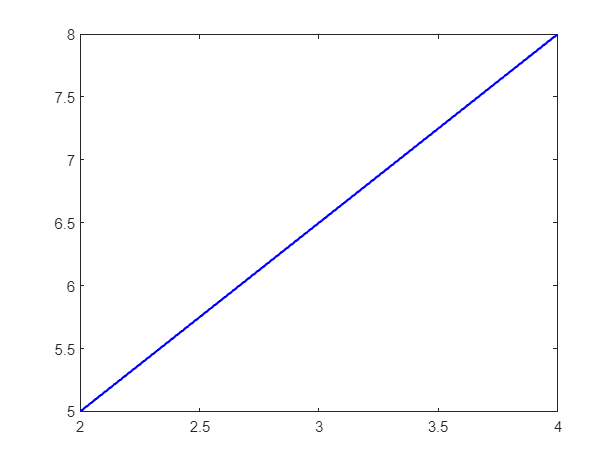

P1=[2 5];
P2=[4 8];
Recta(P1,P2)

3. Diseñe un programa que entregue el n-ésimo término de la siguiente sucesión, en la cual cada término, a partir del cuarto, se obtiene sumando los tres anteriores


$$1,1,1,3,5,9,17,31,57,\ldotp \ldotp \ldotp$$


Compile el programa con el número n=20

% function x=Sucesion_Examen(n)
% %Este programa calcula el i_ésimo término de una sucesión donde, a partir
% %del cuarto número, cada termino se obtiene sumando los tres anteriores
% S=[1 1 1];
% for i=1:(n-3)
%     c=S(end)+S(end-1)+S(end-2);
%     S=[S c];
% end
% x=S(end);

n=20;
x=Sucesion_Examen(n)

x = 46499

4. Diseñe un programa que reciba un entero postivo n y que devuelva la suma de sus divisores positivos.

Compilar el programa con n=80

% function x=Suma_Divisores_Examen(n)
% %Este programa devuelve la suma de los divisores positivos de un número
% %entero postivo
% A=[];
% if n>0
%     if rem(n,1)==0
%         for i=1:n
%             if rem(n,i)==0;
%                 A=[A i];
%             end
%         end
%     else
%         disp 'El número no es un entero'
%     end
% else
%     disp 'El número no es un entero postivo'
% end
% x=sum(A);

n=80;
x=Suma_Divisores_Examen(n)

x = 186

5. Escriba un programa que reciba un vector y entregue otro vector conteniendo los elementos que son números primos. Compilar el programa con el vector


$$5,9,17,31,57,40,51,31,23,7,71,38,33,5,11$$


% function x=Primos_Examen(v)
% %Este programa entrega un vector fila con los elementos del vector v que
% %sean números primos
% n=length(v);
% x=[];
% d=[];
% for i=1:n
%     k=v(i);
%     for j=1:k
%         if rem(k,j)==0
%             d=[d j];
%         end
%     end
%     if length(d)==2
%         x=[x k];
%     end
%     d=[];
% end

v=[5 9 17 31 57 40 51 31 23 7 71 38 33 5 11];
x=Primos_Examen(v)

x =      5    17    31    31    23     7    71     5    11
